syms E I L M I B EA
L=0.1;                   %%m
E=850*1000;             %%pa
mu0=4*pi*10^-7;
Br=0.4;                    %T
M=Br/mu0         %%A/m

M = 3.1831e+05

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;
 ;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.006*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능
EN=2;
figure
hold on
xlim([-10,10])
ylim([-180,180])
MarkerSize = 1

MarkerSize = 1


H=40000;

L1=0.075;

ML=0.008;
L=L-ML;
L1=L1-0.5*ML;
data1x=zeros(1,13);
data1y=zeros(1,13);
thetaset=[ 30 40 50 60 70 80 90 100 110 120 130 140 150];
  for  i=1:13
       thetaB2=thetaset(i);
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
  
        
          data1x(1,i)=100*r;
          data1y(1,i)=x(2)*180/pi;
            
  
  end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 <a href = "matlab

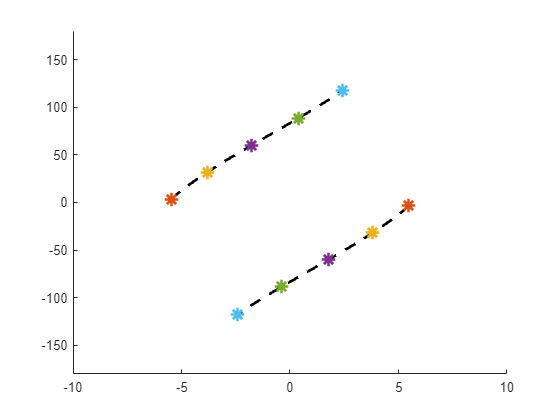


  plot(data1x,data1y,'--k','LineWidth',2)
  plot(-data1x,-data1y,'--k','LineWidth',2)
  %plot(data1x(1),data1y(1),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#0072BD")
  plot(data1x(1),data1y(1),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#D95319")
  plot(data1x(4),data1y(4),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#EDB120")
  plot(data1x(7),data1y(7),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#7E2F8E")
  plot(data1x(10),data1y(10),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#77AC30")
  plot(data1x(13),data1y(13),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#4DBEEE") 
  %plot(-data1x(1),-data1y(1),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#0072BD")
  plot(-data1x(1),-data1y(1),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#D95319")
  plot(-data1x(4),-data1y(4),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#EDB120")
  plot(-data1x(7),-data1y(7),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#7E2F8E")
  plot(-data1x(10),-data1y(10),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#77AC30")
  plot(-data1x(13),-data1y(13),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#4DBEEE")  

syms E I L M I B EA
L=0.1;                   %%m
E=850*1000;             %%pa
mu0=4*pi*10^-7;
Br=0.4;                    %T
M=Br/mu0         %%A/m

M = 3.1831e+05

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;
 ;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.006*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능
EN=2;
figure
hold on
xlim([-L,L])
ylim([-180,180])
MarkerSize = 1

MarkerSize = 1


H=40000;
L1=0.025;
ML=0.008;
L=L-ML;
L1=L1-0.5*ML;

data1x=zeros(1,13);
data1y=zeros(1,13);
thetaset=[ 30 40 50 60 70 80 90 100 110 120 130 140 150];
  for  i=1:13
       thetaB2=thetaset(i);
        
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
                

            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    

        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
        
          data1x(1,i)=r;
          data1y(1,i)=x(2)*180/pi;
            
  
    end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 <a href = "matlab

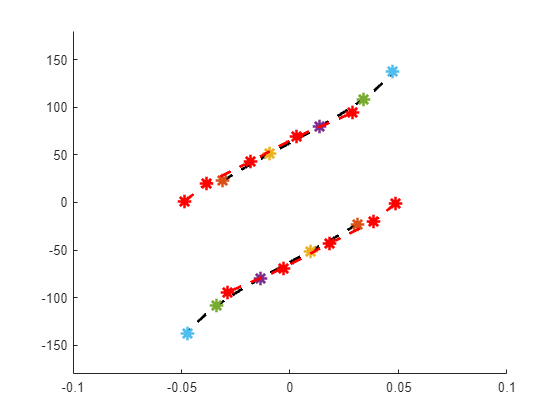


  plot(data1x,data1y,'--k','LineWidth',2)
  plot(-data1x,-data1y,'--k','LineWidth',2)
  %plot(data1x(1),data1y(1),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#0072BD")
  plot(data1x(1),data1y(1),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#D95319")
  plot(data1x(4),data1y(4),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#EDB120")
  plot(data1x(7),data1y(7),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#7E2F8E")
  plot(data1x(10),data1y(10),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#77AC30")
  plot(data1x(13),data1y(13),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#4DBEEE") 
  %plot(-data1x(1),-data1y(1),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#0072BD")
  plot(-data1x(1),-data1y(1),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#D95319")
  plot(-data1x(4),-data1y(4),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#EDB120")
  plot(-data1x(7),-data1y(7),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#7E2F8E")
  plot(-data1x(10),-data1y(10),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#77AC30")
  plot(-data1x(13),-data1y(13),'*','LineWidth',2,'Markersize',10,"MarkeredgeColor","#4DBEEE")  
           exL=2.55;
  
hold on
redata1x=[-0.55 0.04 0.46 0.9 1.26];
  redata1y=[28 52 75 98 130];
  redata1x=0.1*redata1x/exL;
redata2x=[-1.28 -0.9 -0.28 0.37 0.96];
redata2y=[12 33 61 90 118];
redata2x=0.1*redata2x/exL;
redata3x=[-1.24 -0.98 -0.46 0.08 0.73];
redata3y=[1 20 43 69 94];
redata3x=0.1*redata3x/exL;


plot(redata3x,redata3y,'--*r','Markersize',10,'LineWidth',2)
plot(-redata3x,-redata3y,'--*r','Markersize',10,'LineWidth',2)

   
figure
hold on
xlim([-10,10])
ylim([-180,180])
  data0x=zeros(1,15);
data0y=zeros(1,15);

  
  for  i=1:15
        thetaB=i*10;
   fun = @(x) x;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) [abs(x)-pi] ; 
            EA0=[0];
            ceq=@(x) [(E*I*x/(H*M*v11*mu0*sin((thetaB*pi/180)-x)))-L];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            
           x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn)
              Alpha=x;
            Alin=linspace(0,Alpha,1000);

        x=E*I*sin(Alin)/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        y=E*I*(1-cos(Alin))/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
       

        x0=E*I*sin(Alpha)/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        y0=E*I*(1-cos(Alpha))/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        
        %plot(x,y)
        %plot(x0,y0,'ro','MarkerSize',3)
       
        % plot(0,0,'-ro','MarkerSize',3)
          data0x(1,i)=y0;
          data0y(1,i)=Alpha*180/pi;

         data0xt=100*[flip(-data0x),0,data0x];
         data0yt=[flip(-data0y),0,data0y];
            
  

            
  end


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


x = 0.1601


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


x = 0.3202


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.4803


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


x = 0.6403


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.8004


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.9604


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.1205


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.2805


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.4405


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.6004


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.7604


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.9203


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.0801


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.2400


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.3997

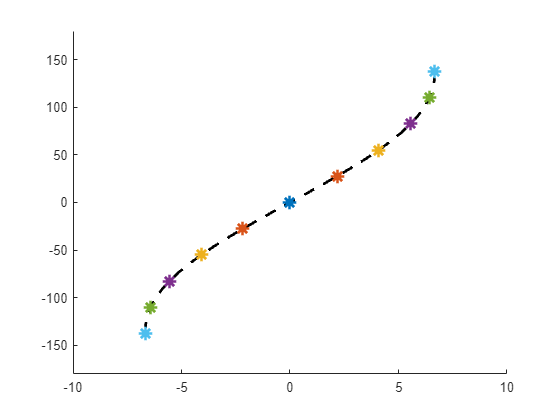

  %plot(data0xt,data0yt,'-r','MarkerSize',2,'LineWidth',2)

 plot(data0xt,data0yt,'--k','LineWidth',2)
  plot(data0xt(16),data0yt(16),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#0072BD")
  plot(data0xt(13),data0yt(13),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#D95319")
  plot(data0xt(10),data0yt(10),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#EDB120")
  plot(data0xt(7),data0yt(7),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#7E2F8E")
  plot(data0xt(4),data0yt(4),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#77AC30")
  plot(data0xt(1),data0yt(1),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#4DBEEE") 
  
  plot(-data0xt(13),-data0yt(13),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#D95319")
  plot(-data0xt(10),-data0yt(10),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#EDB120")
  plot(-data0xt(7),-data0yt(7),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#7E2F8E")
  plot(-data0xt(4),-data0yt(4),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#77AC30")
  plot(-data0xt(1),-data0yt(1),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#4DBEEE")   


syms E I L M I B EA
L=0.1;                   %%m
E=850*1000;             %%pa
mu0=4*pi*10^-7;
Br=0.4;                    %T
M=Br/mu0         %%A/m

M = 3.1831e+05

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;
 ;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.006*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능
EN=2;
figure
hold on
xlim([-10,10])
ylim([-180,180])
MarkerSize = 1

MarkerSize = 1


H=40000;

L1=0.01;

data1x=zeros(1,13);
data1y=zeros(1,13);
thetaset=[31 41 51 61 71 81 91 101 111 121 131 141 151];
  for  i=1:13
        thetaB2=thetaset(i);
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
  
        
          data1x(1,i)=r*100;
          data1y(1,i)=x(2)*180/pi;
            
  
    end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl

%data1x(8)=-0.3;
%data1y(8)=56;
  plot( data1x,data1y,'k','LineWidth',1)
  plot(-data1x,-data1y,'k','LineWidth',1)
  %plot(data1x(1),data1y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#0072BD")
  plot(data1x(1),data1y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#D95319")
  plot(data1x(4),data1y(4),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#EDB120")
  plot(data1x(7),data1y(7),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  plot(data1x(10),data1y(10),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#77AC30")
  plot(data1x(13),data1y(13),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#4DBEEE") 
  %plot(-data1x(1),-data1y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#0072BD")
  plot(-data1x(1),-data1y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#D95319")
  plot(-data1x(4),-data1y(4),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#EDB120")
  plot(-data1x(7),-data1y(7),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#7E2F8E")
  plot(-data1x(10),-data1y(10),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#77AC30")
  plot(-data1x(13),-data1y(13),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#4DBEEE")  
           
L1=0.02;

data2x=zeros(1,13);
data2y=zeros(1,13);
thetaset=[ 30 40 50 60 70 80 90 100 110 120 130 140 150];
  for  i=1:13
        thetaB2=thetaset(i);
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
  
        
          data2x(1,i)=r*100;
          data2y(1,i)=x(2)*180/pi;
            
  
    end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl


  plot(data2x,data2y,'k','LineWidth',1)
  plot(-data2x,-data2y,'k','LineWidth',1)
  %plot(data2x(1),data2y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#0072BD")
  plot(data2x(1),data2y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#D95319")
  plot(data2x(4),data2y(4),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#EDB120")
  plot(data2x(7),data2y(7),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  plot(data2x(10),data2y(10),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#77AC30")
  plot(data2x(13),data2y(13),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#4DBEEE") 
  %plot(-data2x(1),-data2y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#0072BD")
  plot(-data2x(1),-data2y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#D95319")
  plot(-data2x(4),-data2y(4),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#EDB120")
  plot(-data2x(7),-data2y(7),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#7E2F8E")
  plot(-data2x(10),-data2y(10),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#77AC30")
  plot(-data2x(13),-data2y(13),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#4DBEEE")  
           

L1=0.03;

data3x=zeros(1,13);
data3y=zeros(1,13);
thetaset=[ 30 40 50 60 70 80 90 100 110 120 130 140 150];
  for  i=1:13
       thetaB2=thetaset(i);
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
  
        
          data3x(1,i)=r*100;
          data3y(1,i)=x(2)*180/pi;
            
  
    end      


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 

%data3x(10)=0.0278;
%data3y(10)=107.4762;
  plot(data3x,data3y,'k','LineWidth',1)
  plot(-data3x,-data3y,'k','LineWidth',1)
  %plot(data3x(1),data3y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#0072BD")
  plot(data3x(1),data3y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#D95319")
  plot(data3x(4),data3y(4),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#EDB120")
  plot(data3x(7),data3y(7),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  plot(data3x(10),data3y(10),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#77AC30")
  plot(data3x(13),data3y(13),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#4DBEEE") 
  %plot(-data3x(1),-data3y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#0072BD")
  plot(-data3x(1),-data3y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#D95319")
  plot(-data3x(4),-data3y(4),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#EDB120")
  plot(-data3x(7),-data3y(7),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#7E2F8E")
  plot(-data3x(10),-data3y(10),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#77AC30")
  plot(-data3x(13),-data3y(13),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#4DBEEE")  
           

L1=0.04;

data4x=zeros(1,13);
data4y=zeros(1,13);
thetaset=[ 30 40 50 60 70 80 90 100 110 120 130 140 150];
  for  i=1:13
        thetaB2=thetaset(i);
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
  
        
          data4x(1,i)=r*100;
          data4y(1,i)=x(2)*180/pi;
            
  
    end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl


  plot(data4x,data4y,'k','LineWidth',1)
  plot(-data4x,-data4y,'k','LineWidth',1)
  %plot(data4x(1),data4y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#0072BD")
  plot(data4x(1),data4y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#D95319")
  plot(data4x(4),data4y(4),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#EDB120")
  plot(data4x(7),data4y(7),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  plot(data4x(10),data4y(10),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#77AC30")
  plot(data4x(13),data4y(13),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#4DBEEE") 
  %plot(-data4x(1),-data4y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#0072BD")
  plot(-data4x(1),-data4y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#D95319")
  plot(-data4x(4),-data4y(4),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#EDB120")
  plot(-data4x(7),-data4y(7),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#7E2F8E")
  plot(-data4x(10),-data4y(10),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#77AC30")
  plot(-data4x(13),-data4y(13),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#4DBEEE")  
           
L1=0.05;

data5x=zeros(1,13);
data5y=zeros(1,13);
thetaset=[ 30 40 50 60 70 80 90 100 110 120 130 140 150];
  for  i=1:13
       thetaB2=thetaset(i);
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
  
        
          data5x(1,i)=r*100;
          data5y(1,i)=x(2)*180/pi;
            
  
    end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl


  plot(data5x,data5y,'k','LineWidth',1)
  plot(-data5x,-data5y,'k','LineWidth',1)
  %plot(data5x(1),data5y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#0072BD")
  plot(data5x(1),data5y(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#D95319")
  plot(data5x(4),data5y(4),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#EDB120")
  plot(data5x(7),data5y(7),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  plot(data5x(10),data5y(10),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#77AC30")
  plot(data5x(13),data5y(13),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#4DBEEE") 
  %plot(-data5x(1),-data5y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#0072BD")
  plot(-data5x(1),-data5y(1),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#D95319")
  plot(-data5x(4),-data5y(4),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#EDB120")
  plot(-data5x(7),-data5y(7),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#7E2F8E")
  plot(-data5x(10),-data5y(10),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#77AC30")
  plot(-data5x(13),-data5y(13),'*','LineWidth',1,'Markersize',5,"MarkeredgeColor","#4DBEEE")  
           

%v11=0.001*pi*D^2/16;

  data0x=zeros(1,15);
data0y=zeros(1,15);
L=0.1;
  
  for  i=1:15
        thetaB=i*10;
   fun = @(x) x;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) [abs(x)-pi] ; 
            EA0=[0];
            ceq=@(x) [(E*I*x/(H*M*v11*mu0*sin((thetaB*pi/180)-x)))-L];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            
           x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn)
              Alpha=x;
            Alin=linspace(0,Alpha,1000);

        x=E*I*sin(Alin)/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        y=E*I*(1-cos(Alin))/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
       

        x0=E*I*sin(Alpha)/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        y0=E*I*(1-cos(Alpha))/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        
        %plot(x,y)
        %plot(x0,y0,'ro','MarkerSize',3)
       
        % plot(0,0,'-ro','MarkerSize',3)
          data0x(1,i)=y0;
          data0y(1,i)=Alpha*180/pi;

         data0xt=100*[flip(-data0x),0,data0x];
         data0yt=[flip(-data0y),0,data0y];
            
  

            
  end


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.1612


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.3223


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.4835


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.6446


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


x = 0.8057


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.9669


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


x = 1.1280


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.2891


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.4501


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.6112


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.7722


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.9332


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.0942


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.2552


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.4161

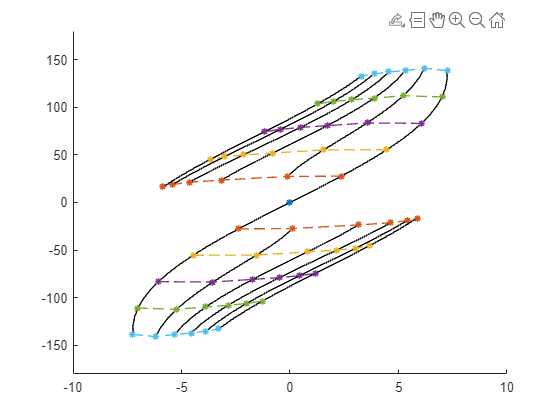

  %plot(data0xt,data0yt,'-r','MarkerSize',2,'LineWidth',2)

 plot(data0xt,data0yt,'k','LineWidth',1)
  plot(data0xt(16),data0yt(16),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#0072BD")
  plot(data0xt(13),data0yt(13),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#D95319")
  plot(data0xt(10),data0yt(10),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#EDB120")
  plot(data0xt(7),data0yt(7),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  plot(data0xt(4),data0yt(4),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#77AC30")
  plot(data0xt(1),data0yt(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#4DBEEE") 
  
  plot(-data0xt(13),-data0yt(13),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#D95319")
  plot(-data0xt(10),-data0yt(10),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#EDB120")
  plot(-data0xt(7),-data0yt(7),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  plot(-data0xt(4),-data0yt(4),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#77AC30")
  plot(-data0xt(1),-data0yt(1),'*','Markersize',5,'Linewidth',1,"MarkeredgeColor","#4DBEEE")   

orth0x=[-data0xt(16) data1x(1) data2x(1) data3x(1) data4x(1) data5x(1)];
  orth0y=[-data0yt(16) data1y(1) data2y(1) data3y(1) data4y(1) data5y(1)];
  %plot(orth0x,orth0y,'--','LineWidth',1,'Color',"#0072BD")
  %plot(-orth0x,-orth0y,'--','LineWidth',1,'Color',"#0072BD")
  orth1x=[-data0xt(13) data1x(1) data2x(1) data3x(1) data4x(1) data5x(1)];
  orth1y=[-data0yt(13) data1y(1) data2y(1) data3y(1) data4y(1) data5y(1)];
  plot(orth1x,orth1y,'--','LineWidth',1,'Color',"#D95319" )
  plot(-orth1x,-orth1y,'--','LineWidth',1,'Color',"#D95319" )
  orth2x=[-data0xt(10) data1x(4) data2x(4) data3x(4) data4x(4) data5x(4)];
  orth2y=[-data0yt(10) data1y(4) data2y(4) data3y(4) data4y(4) data5y(4)];
  plot(orth2x,orth2y,'--','LineWidth',1,'Color',"#EDB120" )
  plot(-orth2x,-orth2y,'--','LineWidth',1,'Color',"#EDB120" )
  orth3x=[-data0xt(7) data1x(7) data2x(7) data3x(7) data4x(7) data5x(7)];
  orth3y=[-data0yt(7) data1y(7) data2y(7) data3y(7) data4y(7) data5y(7)];
  plot(orth3x,orth3y,'--','LineWidth',1,'Color',"#7E2F8E" )
  plot(-orth3x,-orth3y,'--','LineWidth',1,'Color',"#7E2F8E" )
  orth4x=[-data0xt(4) data1x(10) data2x(10) data3x(10) data4x(10) data5x(10)];
  orth4y=[-data0yt(4) data1y(10) data2y(10) data3y(10) data4y(10) data5y(10)];
  plot(orth4x,orth4y,'--','LineWidth',1,'Color',"#77AC30" )
  plot(-orth4x,-orth4y,'--','LineWidth',1,'Color',"#77AC30" )
  orth5x=[-data0xt(1) data1x(13) data2x(13) data3x(13) data4x(13) data5x(13)];
  orth5y=[-data0yt(1) data1y(13) data2y(13) data3y(13) data4y(13) data5y(13)];
  plot(orth5x,orth5y,'--','LineWidth',1,'Color',"#4DBEEE" )
  plot(-orth5x,-orth5y,'--','LineWidth',1,'Color',"#4DBEEE" )

syms E I L M I B EA
L=0.1;                   %%m
E=850*1000;             %%pa
mu0=4*pi*10^-7;
Br=0.4;                    %T
M=Br/mu0         %%A/m

M = 3.1831e+05

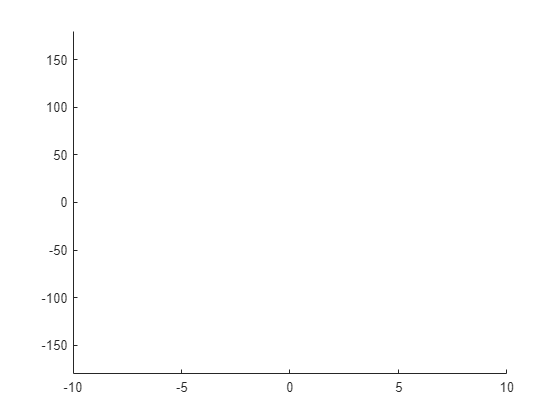

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;
 ;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.006*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능
EN=2;
figure
hold on
xlim([-10,10])
ylim([-180,180])

MarkerSize = 1

MarkerSize = 1


H=40000;   
figure
hold on
xlim([-10,10])
ylim([-180,180])
  data0x=zeros(1,15);
data0y=zeros(1,15);

  
  for  i=1:15
        thetaB=i*10;
   fun = @(x) x;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) [abs(x)-pi] ; 
            EA0=[0];
            ceq=@(x) [(E*I*x/(H*M*v11*mu0*sin((thetaB*pi/180)-x)))-L];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            
           x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn)
              Alpha=x;
            Alin=linspace(0,Alpha,1000);

        x=E*I*sin(Alin)/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        y=E*I*(1-cos(Alin))/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
       

        x0=E*I*sin(Alpha)/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        y0=E*I*(1-cos(Alpha))/(H*M*v11*mu0*sin((thetaB*pi/180)-Alpha));
        
        %plot(x,y)
        %plot(x0,y0,'ro','MarkerSize',3)
       
        % plot(0,0,'-ro','MarkerSize',3)
          data0x(1,i)=y0;
          data0y(1,i)=Alpha*180/pi;

         data0xt=[flip(-data0x),0,data0x];
         data0yt=[flip(-data0y),0,data0y];
            
  

            
  end


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.1612


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.3223


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.4835


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.6446


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


x = 0.8057


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 0.9669


제약 조건을 충족하는 국소 최솟값을 찾았습니다.

목적 함수가 최적성 허용오차의 값 이내에서 실현 가능한 방향에서 감소하지 않고 
제약 조건이 제약 조건 허용오차의 값 이내에서 충족되기 때문에 
최적화가 완료되었습니다.

<중지 기준 세부 정보>


x = 1.1280


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.2891


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.4501


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.6112


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.7722


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 1.9332


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.0942


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.2552


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>


x = 2.4161

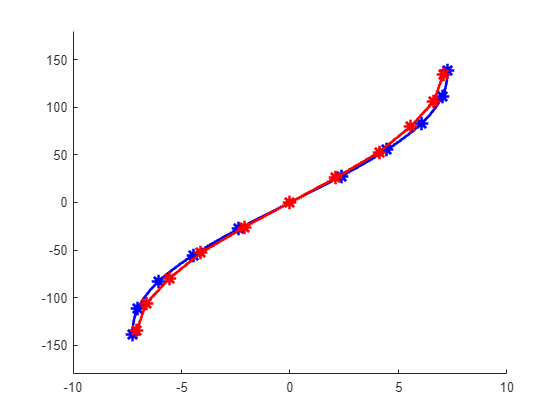

  %plot(data0xt,data0yt,'-r','MarkerSize',2,'LineWidth',2)

 plot(100*data0xt,data0yt,'-*b','Markersize',10,'LineWidth',2,'MarkerIndices',1:3:length(data0yt))
  %plot(data0xt(16),data0yt(16),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#0072BD")
  %plot(data0xt(13),data0yt(13),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#D95319")
  %plot(data0xt(10),data0yt(10),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#EDB120")
 %plot(data0xt(7),data0yt(7),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  %plot(data0xt(4),data0yt(4),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#77AC30")
  %plot(data0xt(1),data0yt(1),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#4DBEEE") 
  
  %plot(-data0xt(13),-data0yt(13),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#D95319")
  %plot(-data0xt(10),-data0yt(10),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#EDB120")
  %plot(-data0xt(7),-data0yt(7),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#7E2F8E")
  %plot(-data0xt(4),-data0yt(4),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#77AC30")
  %plot(-data0xt(1),-data0yt(1),'*','Markersize',10,'Linewidth',1,"MarkeredgeColor","#4DBEEE")   
    exL=2.55;        
  redata0x=[0.54 1.05 1.42 1.69 1.8];
  redata0y=[26 53 80 106 134];
redata0x=0.1*redata0x/exL;
exdata0x=[flip(-redata0x),0,redata0x];
exdata0y=[flip(-redata0y),0,redata0y];
plot(100*exdata0x,exdata0y,'-*r','Markersize',10,'LineWidth',2)

x=[data0x(3:15),flip(redata0x)];
y=[data0y(3:15),flip(redata0y)];
polyarea(100*x,y)

ans = 30.4772

figure

L1=0.025;
thetaB2=0;
contx=linspace(-180,180);
conty=linspace(-180,180);
[X,Y] = meshgrid(contx,conty);
ela=((E.*I.*(X*pi/180).^2)./L1 )+E.*I.*(((Y-X)*pi/180).^2)./(L-L1);
mag=-H*M*v11*mu0*cos(X*pi/180-thetaB2*pi/180)+H*M*v2*mu0*cos(Y*pi/180-thetaB2*pi/180);
z=ela-mag;
contour(X,Y,z,30, 'LineWidth',2)

figure
plot3(X,Y,z)

syms E I L M I B EA
L=0.1;                   %%m
E=950*1000;             %%pa
mu0=4*pi*10^-7;
Br=0.4;                    %T
M=Br/mu0         %%A/m

M = 3.1831e+05

D=0.002;
D2=0.001;
A=D^2*pi/4;
I=D^4*pi/64-D2^4*pi/64;
 ;                %%A/m 
v1=0.002*pi*D^2/4;      %%h=2mm
v11=0.006*pi*D^2/16;        %%h=4mm
v2=0.002*pi*D^2/4;
dl = L/10000 ;        %% 분해능
EN=2;
figure
hold on
xlim([-10,10])
ylim([-180,180])
MarkerSize = 1

MarkerSize = 1


H=40000;
L1=0.025;
ML=0.008;
L=L-ML;
L1=L1-0.5*ML;
data1x=zeros(1,13);
data1y=zeros(1,13);
thetaset=[ 30 40 50 60 70 80 90 100 110 120 130 140 150];
  for  i=1:13
        thetaB2=thetaset(i);
            fun = @(x) x(1)^2+x(2)^2;
            A = [];
            b = [];
            Aeq = [];
            beq = [];
            lb = [];
            ub = [];
            c = @(x) abs(abs(x(1))-abs(x(2)))-pi;
            EA0=[0 0];
            ceq=@(x) [EN*E*I*x(1)/-((H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))-(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L1;...
            (E*I*(x(2)-x(1))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))-L+L1];
            nonlinfcn = @(x)deal(c(x),ceq(x));
            x = fmincon(fun,EA0,A,b,Aeq,beq,lb,ub,nonlinfcn);
            A1lin=linspace(0,x(1),500);
            A2lin=linspace(x(1),x(2),500);
            x1=EN*E*I*sin(A1lin)/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y1=EN*E*I*(1-cos(A1lin))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
    
        x10=EN*E*I*sin(x(1))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
        y10=EN*E*I*(1-cos(x(1)))/(-(H*M*v11*mu0*sin((thetaB2*pi/180)-x(1)))+(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))));
   
        x2=(E*I*(sin(A2lin)-sin(x(1)))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+x10;
        y2=(E*I*(cos(x(1))-cos(A2lin))/(H*M*v2*mu0*sin((thetaB2*pi/180)-x(2))))+y10;
    
    
        xtotal=[x1,x2];
        ytotal=[y1,y2];
 


        r=ytotal(1000);
        
         data1x(1,i)=r;
          data1y(1,i)=x(2)*180/pi;
            
  
    end      


국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 제약 조건 허용오차의 값 이내에서 
충족되기 때문에 fmincon이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다. 제약 조건이 충족되었습니다.

현재 스텝의 크기가 스텝 크기 허용오차 값보다 작고 
제약 조건이 <a href = "matl

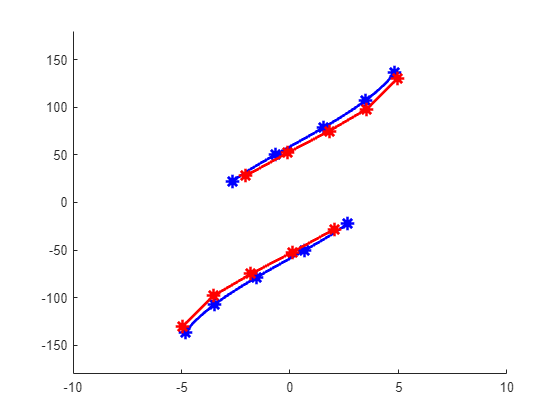


  plot(100*data1x,data1y,'-*b','Markersize',10,'LineWidth',2,'MarkerIndices',1:3:length(data1y))
  plot(100*-data1x,-data1y,'-*b','Markersize',10,'LineWidth',2,'MarkerIndices',1:3:length(data1y))
  %plot(data1x(1),data1y(1),'*','Markersize',10,'Linewidth',2,"MarkeredgeColor","#0072BD")
   
           exL=2.55;
  
hold on
redata1x=[-0.52 -0.03 0.46 0.9 1.26];
  redata1y=[28 52 75 98 130];
  redata1x=0.1*redata1x/exL;
redata2x=[-1.24 -0.9 -0.28 0.37 0.96];
redata2y=[12 33 61 90 118];
redata2x=0.1*redata2x/exL;
redata3x=[-1.24 -0.98 -0.46 0.08 0.73];
redata3y=[1 20 43 69 94];
redata3x=0.1*redata3x/exL;


plot(100*redata1x,redata1y,'-*r','Markersize',10,'LineWidth',2)
plot(100*-redata1x,-redata1y,'-*r','Markersize',10,'LineWidth',2)


x=[data1x,flip(redata1x)];
y=[data1y,flip(redata1y)];
polyarea(x,y)

ans = 0.4693